clc; clear;


## --- Simulation Parameters ---


Ts = 0.1;
N = 300;
minDist = 6;

profile = 1;


## --- Lead vehicle velocity profile ---



if profile == 1
    t = (0:N-1)' * Ts;
    v_lead = 10 + 2 * sin(2 * pi * 0.1 * t);
elseif profile == 2
    v_lead = zeros(N,1);
    v_lead(1:20) = linspace(0, 10, 20); 
    v_lead(21:80) = 10;         
    v_lead(81:100) = linspace(10, 0, 20);
    v_lead(101:end) = 0;
end

x_lead = zeros(N,1); 
for k = 2:N
    x_lead(k) = x_lead(k-1) + Ts * v_lead(k-1);
end


## --- Ego vehicle model (double integrator) ---


A = [1 Ts; 0 1];
B = [0; Ts];
C = eye(2);  
D = 0;

plant = ss(A, B, C, D, Ts);
plant = minreal(plant);
mpcobj = mpc(plant, Ts, 10, 3);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 


mpcobj.Weights.OutputVariables = [4 2];  
mpcobj.Weights.ManipulatedVariables = 0.1;
mpcobj.Weights.ManipulatedVariablesRate = 0.1;
mpcobj.MV.Min = -3;
mpcobj.MV.Max = 2;


## --- Initial Conditions ---


x_ego = zeros(2,1);       
x_lead0 = 6;             
x_lead = x_lead + x_lead0; 

mpc_state = mpcstate(mpcobj);

   Assuming no disturbance added to measured output #1.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


ulog = zeros(N,1);
dist = zeros(N,1);
v_ego_log = zeros(N,1);

k_gain = 0.1;      
v_bar = 8;       
A_gain = 1.0;     
B_gain = 1.0;   


## --- Simulation Loop ---

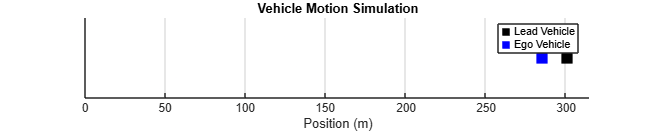


for k = 1:N
    dist_k = x_lead(k) - x_ego(1);  
    y = x_ego;                  

    D = x_lead(k) - x_ego(1); 
    v = x_ego(2);             
    vl = v_lead(k);         
    
    Vd = max(0, min(k_gain * (D - minDist), v_bar));
    Wvl = min(vl, v_bar);
    
    v_ref = A_gain * (Vd - v) + B_gain * (Wvl - v) + v;

    r = [x_lead(k) - minDist; v_ref];

    u = mpcmove(mpcobj, mpc_state, y, r);

    u = min(max(u, -3), 2);


    x_ego = A * x_ego + B * u;

    ulog(k) = u;
    dist(k) = dist_k;
    v_ego_log(k) = x_ego(2);
end


roadLength = max(x_lead) + 10;

figure;
hFig = gcf;
hFig.Position(3:4) = [1000, 200];  
axis([0 roadLength -2 2]);
hold on;
grid on;

lead_plot = plot(0, 0, 'ks', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
ego_plot = plot(0, 0, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
title('Vehicle Motion Simulation');
xlabel('Position (m)');
yticks([]);
legend('Lead Vehicle', 'Ego Vehicle');

for k = 1:5:N
    set(lead_plot, 'XData', x_lead(k));
    set(ego_plot, 'XData', x_lead(k) - dist(k));
    drawnow;
    pause(0.05);
end

## --- Plotting ---

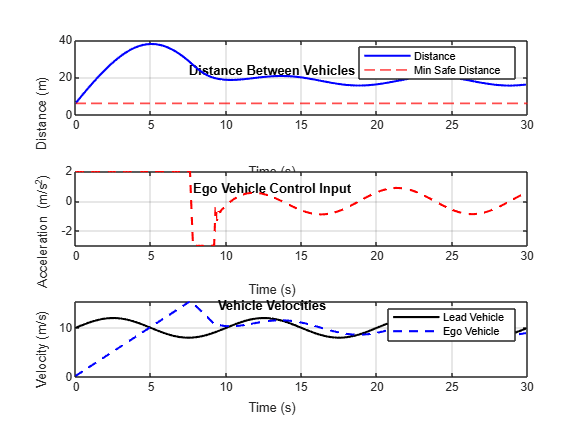


t = (0:N-1)*Ts;

figure;

subplot(3,1,1)
plot(t, dist, 'b-', 'LineWidth', 1.5); hold on;
yline(minDist, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Distance (m)');
title('Distance Between Vehicles'); grid on;
legend('Distance', 'Min Safe Distance');

subplot(3,1,2)
plot(t, ulog, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');
title('Ego Vehicle Control Input'); grid on;

subplot(3,1,3)
plot(t, v_lead, 'k-', t, v_ego_log, 'b--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Velocity (m/s)');
legend('Lead Vehicle', 'Ego Vehicle');
title('Vehicle Velocities'); grid on;
title('Vehicle Velocities'); grid on;